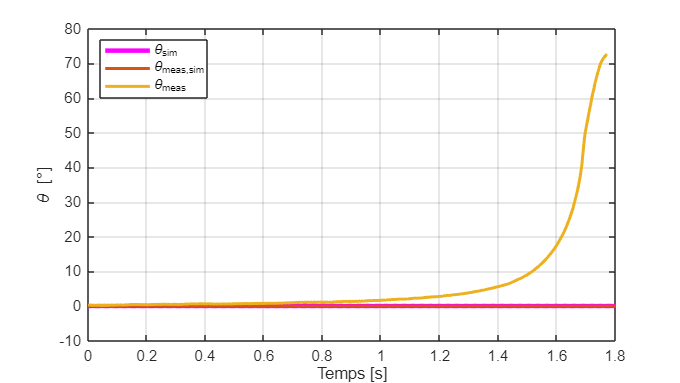

run("complete/complete_parameters.m")

% Free Fall (from .01°)
% Initial state
X0 = [0; 0; 0.00003*pi/180; 0];


% Simulate
Tsim = 1.8;
t = 0:0.001:Tsim;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

theta_v = out.simout.signals.values(:,3);
theta_mes = out.theta_measure.signals.values();
t_v = out.tout;
% Read CSV
data = readmatrix('./data/free_fall_positive.csv');
tm_v= data(:,1);
thetam_v = data(:,5);


% theta
figure('Units','centimeters','Position',[2 2 16 9]);

hold on
plot(t_v, theta_v*180/pi, 'LineWidth', 3, 'Color', 'magenta', 'DisplayName', '\theta_{sim}');
plot(t_v, theta_mes*180/pi, 'LineWidth', 2, 'DisplayName', '\theta_{meas,sim}');
plot(tm_v/1000, thetam_v, 'LineWidth', 2, 'DisplayName', '\theta_{meas}');

xlabel('Temps [s]');
ylabel('\theta [°]');
legend('Location','best');
grid on;
box on;
hold off;

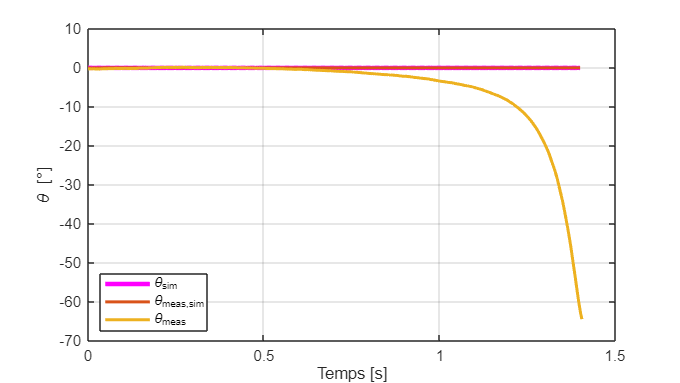

%exportgraphics(gca,'results/free_fall_positive.pdf','ContentType','vector');
% Simulate
X0 = [0; 0; -0.0005*pi/180; 0];
Tsim = 1.4;
t = 0:0.001:Tsim;
v_ref = 0 * ones(size(t));
input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

theta_v = out.simout.signals.values(:,3);
theta_mes = out.theta_measure.signals.values();
t_v = out.tout;
% Read CSV
data = readmatrix('./data/free_fall_negative.csv');
tm_v= data(:,1);
thetam_v = data(:,5);

% theta
figure('Units','centimeters','Position',[2 2 16 9]);

hold on
plot(t_v, theta_v*180/pi, 'LineWidth', 3, 'Color', 'magenta', 'DisplayName', '\theta_{sim}');
plot(t_v, theta_mes*180/pi, 'LineWidth', 2, 'DisplayName', '\theta_{meas,sim}');
plot(tm_v/1000, thetam_v, 'LineWidth', 2, 'DisplayName', '\theta_{meas}');

xlabel('Temps [s]');
ylabel('\theta [°]');
legend('Location','best');
grid on;
box on;
hold off;

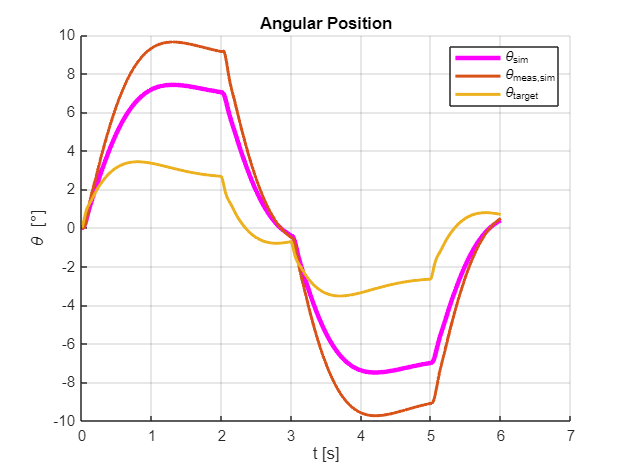

%exportgraphics(gca,'results/free_fall_negative.pdf','ContentType','vector');

% Trapezoidal (0,0.3,0) in 5s, 2.5s rise/fall
% Simulate
X0 = [0; 0; 0; 0];

% Trapezoidal/Triangular velocity reference
v_peak = 0.7;        % m/s
Tsim = 6;
t = 0:0.001:Tsim;

t_rise = 2;
t_fall = 2;
t_tot  = 5;

t_flat = t_tot - (t_rise + t_fall);

v_ref = zeros(size(t));

for i = 1:length(t)

    if t(i) < t_rise
        % Ramp up
        v_ref(i) = v_peak * t(i) / t_rise;

    elseif t(i) < (t_rise + t_flat)
        % Constant section
        v_ref(i) = v_peak;

    elseif t(i) < t_tot
        % Ramp down
        v_ref(i) = v_peak * (t_tot - t(i)) / t_fall;

    else
        % After profile ends
        v_ref(i) = 0;
    end

end

input_signal = [t' v_ref'];
out = sim("complete/complete_robot_sim.slx");

theta_v = out.simout.signals.values(:,3);
theta_mes = out.theta_measure.signals.values();
x_v = out.simout.signals.values(:,1); 
dx_v = out.simout.signals.values(:,2); 
dtheta_v = out.simout.signals.values(:,4);
torque_v = out.torque.signals.values();
domega = out.domega.signals.values();
ddx = out.ddx.signals.values(1,:);
theta_target = out.theta_target.signals.values();
t_v = out.tout;


data = readmatrix('./data/trapezoidal_move_pos_2.csv');
tm_v = data(:,1)/1000;
dxm_v = data(:,4);
dx_targetm_v = data(:,3);
xm_v = data(:,7)/1000;

xm_v = xm_v - xm_v(1); % Shifts to 0
tm_v = tm_v-tm_v(1); % Shifts to 0

% theta
figure;
hold on;
plot(t_v, theta_v*180/pi, "LineWidth", 3,"Color","magenta","DisplayName","\theta_{sim}");
plot(t_v, theta_mes, 'LineWidth', 2,"DisplayName","\theta_{meas,sim}");
plot(t_v, theta_target, 'LineWidth', 2,"DisplayName","\theta_{target}");
xlabel('t [s]');
ylabel('\theta [°]');
title('Angular Position');
legend('show');
grid on;
hold off;

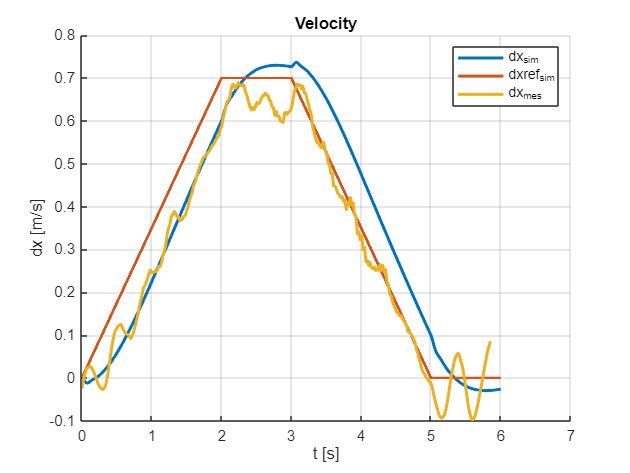


figure;
hold on;
plot(t_v, dx_v, "LineWidth", 2,"DisplayName","dx_{sim}");
plot(t, v_ref, "LineWidth", 2,"DisplayName","dxref_{sim}");
plot(tm_v,dxm_v, "LineWidth",2,"DisplayName","dx_{mes}");
xlabel('t [s]');
ylabel('dx [m/s]');
title('Velocity');
legend("show");
grid on;
hold off;

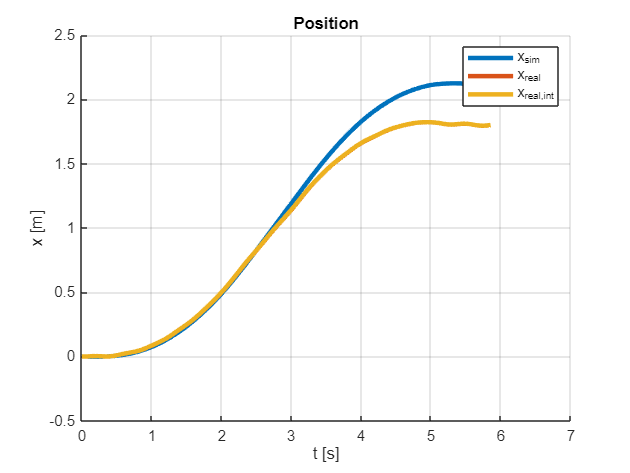



figure;
hold on;
plot(t_v, x_v, "LineWidth", 3,"DisplayName","x_{sim}");
plot(tm_v,xm_v, "LineWidth",3,"DisplayName","x_{real}");
plot(tm_v,cumtrapz(tm_v, dxm_v),"LineWidth",3,"DisplayName","x_{real,int}")
xlabel('t [s]');
ylabel('x [m]');
title('Position');
legend('show');

grid on;
hold off;